Bewegungsgleichung:

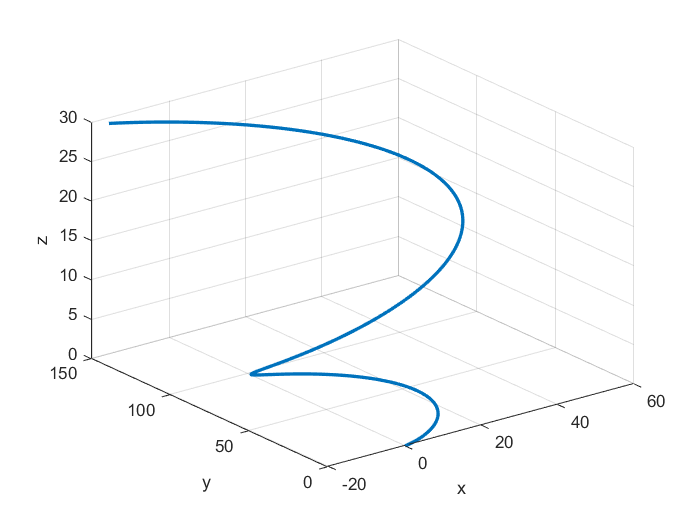

R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.2 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;
figure;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

Gemessene Werte:

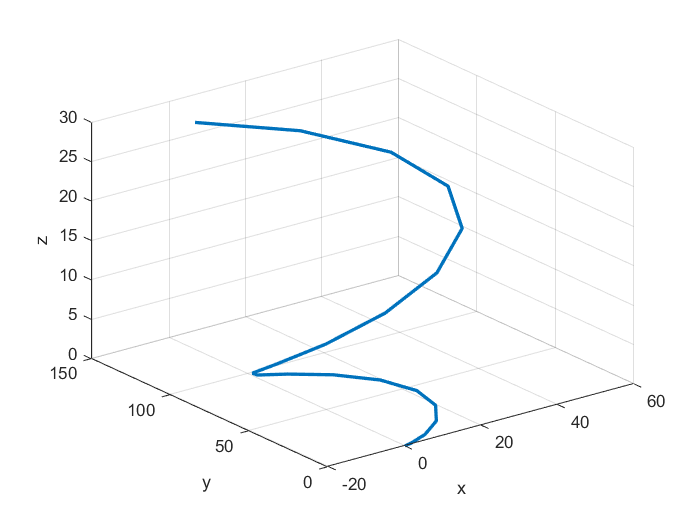

R_measured = extract_every_third_column(R);
figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% y = awgn(R_measured,5);
% 
% figure;
% plot3(y(1,:), y(2,:), y(3,:), 'LineWidth', 2);
% xlabel('x');
% ylabel('y');
% zlabel('z');
% grid on;


R_measured(3,:)

ans =     5.7574    5.8199    3.0941    0.8075    5.1651    6.9832    8.0163    8.3347    2.1478    9.8407   10.1927   13.3158    8.8762    5.9364   13.3731   17.6370   18.2279   30.0567   17.8846   21.1930


for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end
R_measured(3,:)

ans =     5.2467    7.5685    4.4122    2.2039    4.6552    7.3559    9.5065   10.0687    2.8217    8.6678   10.8081   11.6040    8.5031    6.6041   15.1080   18.8808   18.1661   31.0837   17.5528   23.0801


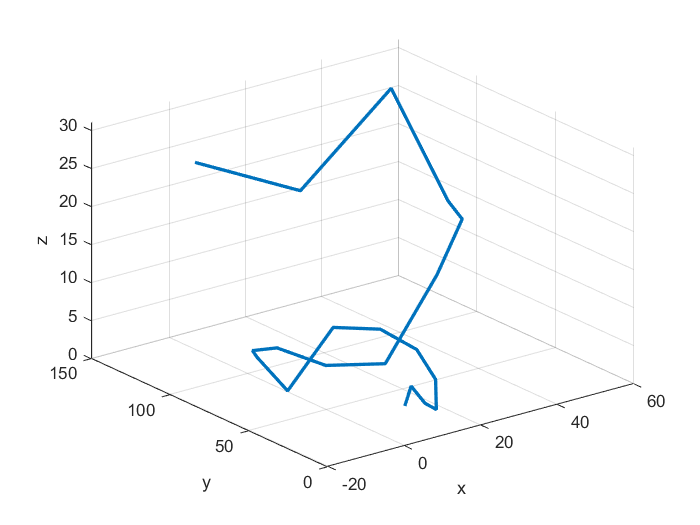

figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% Gegebene 3D-Punkte (X, Y, Z)
% R_measured = 3x20
points = transpose(R_measured)

points =          0         0    5.2467
    1.8277    0.4155    7.5685
    6.5599    3.1358    4.4122
   12.2030    9.6079    2.2039
   16.2176   19.8459    4.6552
   16.4291   32.3359    7.3559
   11.8577   44.4655    9.5065
    3.1897   53.3595   10.0687
   -7.2818   56.8673    2.8217
  -16.2617   54.3896    8.6678



% Zeitpunkte für die Punkte (optional)
% t = 1x200
t_measured = extract_every_third_column(t)

t_measured =          0    1.0050    2.0101    3.0151    4.0201    5.0251    6.0302    7.0352    8.0402    9.0452   10.0503   11.0553   12.0603   13.0653   14.0704   15.0754   16.0804   17.0854   18.0905   19.0955


% time = 20x1
time = transpose(t_measured)

time =          0
    1.0050
    2.0101
    3.0151
    4.0201
    5.0251
    6.0302
    7.0352
    8.0402
    9.0452




% Berechnung der Geschwindigkeit
velocityX = diff(points(:, 1)) ./ diff(time);
velocityY = diff(points(:, 2)) ./ diff(time);
velocityZ = diff(points(:, 3)) ./ diff(time);

% Geschwindigkeitsvektor erstellen
% velocityVector = [VX1, VY1, VZ1;
%                   VX2, VY2, VZ2;
%                   VX3, VY3, VZ3;
%                   ...];
velocityVector = [velocityX, velocityY, velocityZ];

% Berechnung der Beschleunigung
accelerationX = diff(velocityVector(:, 1)) ./ diff(time(1:end-1));
accelerationY = diff(velocityVector(:, 2)) ./ diff(time(1:end-1));
accelerationZ = diff(velocityVector(:, 3)) ./ diff(time(1:end-1));

% Beschleunigungsvektor erstellen
accelerationVector = [accelerationX, accelerationY, accelerationZ];


% Ergebnis ausgeben
disp(velocityVector);

    1.8186    0.4134    2.3102
    4.7085    2.7067   -3.1405
    5.6149    6.4397   -2.1973
    3.9945   10.1869    2.4391
    0.2105   12.4275    2.6872
   -4.5486   12.0690    2.1399
   -8.6246    8.8496    0.5594
  -10.4192    3.4902   -7.2108
   -8.9350   -2.4653    5.8168
   -4.1590   -7.0864    2.1296
    2.8402   -8.6459    0.7919
   10.1489   -6.1916   -3.0854
   15.5268    0.0776   -1.8895
   17.0678    8.7608    8.4613
   13.8141   17.5641    3.7539
    6.1354   23.9042   -0.7111
   -4.2550   25.6479   12.8530
  -14.6777   21.7788  -13.4632
  -22.1775   12.7942    5.4996



% Ergebnis ausgeben
disp(accelerationVector);

    2.8754    2.2819   -5.4234
    0.9019    3.7143    0.9385
   -1.6122    3.7284    4.6132
   -3.7652    2.2295    0.2468
   -4.7352   -0.3568   -0.5446
   -4.0556   -3.2033   -1.5726
   -1.7856   -5.3325   -7.7313
    1.4768   -5.9258   12.9625
    4.7521   -4.5980   -3.6688
    6.9642   -1.5516   -1.3310
    7.2722    2.4419   -3.8579
    5.3510    6.2379    1.1899
    1.5333    8.6398   10.2991
   -3.2375    8.7593   -4.6839
   -7.6403    6.3084   -4.4426
  -10.3384    1.7349   13.4962
  -10.3706   -3.8497  -26.1846
   -7.4623   -8.9397   18.8680



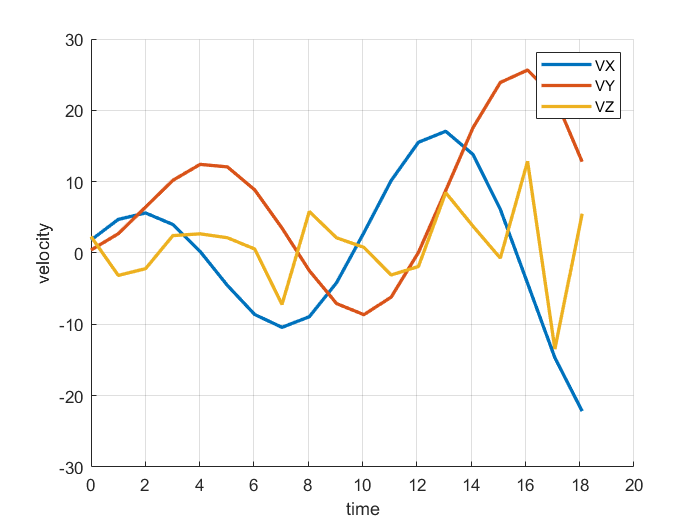


velocityVector = transpose(velocityVector);
time = transpose(time(1:end-1));

figure;
hold on;

plot(time, velocityVector(1,:), 'LineWidth', 2);
plot(time, velocityVector(2,:), 'LineWidth', 2);
plot(time, velocityVector(3,:), 'LineWidth', 2);

xlabel('time');
ylabel('velocity');
grid on;

legend('VX', 'VY', 'VZ');

function new_array = extract_every_third_column(R)
    new_array = R(:, 1:10:end);
end